clc
clear all
format long g

% INPUTS
NELEM_vec = [5 10 20 50 100 200];  % Number of elements vector

% Define cell arrays to store varying sizes of matrices
STRESS_GLO = cell(length(NELEM_vec), 1);
STRAIN_GLO = cell(length(NELEM_vec), 1);
d_GLO = cell(length(NELEM_vec), 1);
COOR_gauss = cell(length(NELEM_vec), 1);  % Cell array to store COOR_gauss for each NELEM
COOR = cell(length(NELEM_vec), 1);        % Cell array to store COOR for each NELEM
stepsPOST = cell(length(NELEM_vec), 1);
TIMES = cell(length(NELEM_vec), 1);

for e = 1:length(NELEM_vec)
    NELEM = NELEM_vec(e);  % Number of elements
    nsteps = NELEM + 1;  % Number of steps
    stepsPOST{e} = 1:round(nsteps/3):nsteps;  % Steps to post-process

    % Material and geometric properties
    A0 = 1e-2; %m  % Reference AREA
    E0 = 10; % MPa  % Reference Young's Modulus
    sigma_0 = 1; %MPa  % Saturation stress
    L = 1; %m  % Length of the beam
    T = 1; % s Final time
    um = 0.2 * L; %m   % Maximum displacement
    AreaFUN = @(x) (A0 * (1 + 2 * (x/L) .* (x/L - 1)));  % Area function
    stressFUN = @(strain) (sigma_0 * (1 - exp(-E0/sigma_0 * strain)));  % Stress function
    DerStressFUN = @(strain) (E0 * exp(-E0/sigma_0 * strain));  % Derivative function
    r = [1, NELEM + 1];  % Boundary condition indices
    uEND = @(t) (t/T * um);  % Prescribed displacement as a function of time
    TOL_residual = 1e-6;  % Convergence tolerance
    MAXITER = 50;  % Maximum number of Newton-Raphson iterations

    % MESH INFORMATION
    nnode = NELEM + 1;
    COOR{e} = linspace(0, L, nnode)';  % Store COOR for current NELEM in cell array
    CN = [(1:(nnode - 1))', (2:nnode)'];
    l = setdiff(1:nnode, r);
    d = zeros(nnode, 1);  % Displacement at time tn

    TIMES{e} = linspace(0, T, nsteps);

    % Initialize post-processing arrays for current NELEM
    STRESS_GLO{e} = zeros(NELEM, nsteps);
    STRAIN_GLO{e} = zeros(NELEM, nsteps);
    d_GLO{e} = zeros(nnode, length(stepsPOST));

    iplot = 1;

    % Time-stepping loop
    for istep = 1:nsteps
        t = TIMES{e}(istep);
        d(nnode) = uEND(t);

        d_k = d;
        k = 0;
        while k <= MAXITER
            [Residual, STRAIN, STRESS] = AssemblyFint(COOR{e}, CN, d_k, stressFUN, AreaFUN);
            normRESIDUAL = norm(Residual(l));
            if normRESIDUAL < TOL_residual
                d = d_k;
                break;
            end

            K = AssemblyKnon(COOR{e}, CN, d_k, AreaFUN, DerStressFUN);
            Delta_d_l = -K(l, l) \ Residual(l);
            d_k(l) = d_k(l) + Delta_d_l;
            k = k + 1;
        end

        if k > MAXITER
            error('The Newton-R. algorithm failed to converge');
        else
            d = d_k;
            d_GLO{e}(:, iplot) = d;
            STRAIN_GLO{e}(:, iplot) = STRAIN;
            STRESS_GLO{e}(:, iplot) = STRESS;
            iplot = 1 + iplot;
        end
    end

    % Calculate and store Gauss coordinates for current NELEM
    COOR_gauss{e} = (COOR{e}(CN(:, 2)) + COOR{e}(CN(:, 1))) / 2;
end

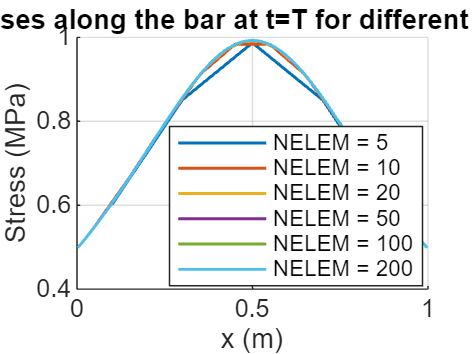


%% PLOTS

% Plot stresses along the bar at the last timestep for each NELEM value
figure;
hold on;
xlabel('x (m)');
ylabel('Stress (MPa)');
title('Stresses along the bar at t=T for different NELEM');
legendEntries = cell(length(NELEM_vec), 1);

% Loop through each NELEM value to plot the stresses at the last timestep
for e = 1:length(NELEM_vec)
    plot(COOR_gauss{e}, STRESS_GLO{e}(:, end), 'LineWidth', 1);
    legendEntries{e} = ['NELEM = ', num2str(NELEM_vec(e))];
end

grid on;
legend(legendEntries, 'Location', 'Best');

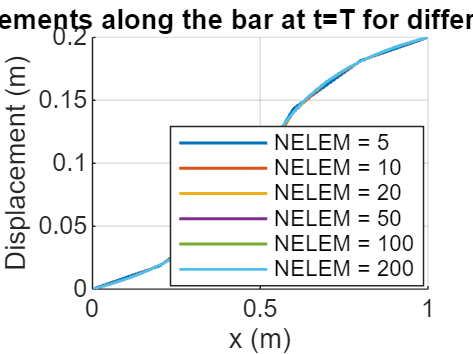



% Plot displacements along the bar at the last timestep for each NELEM value
figure;
hold on;
xlabel('x (m)');
ylabel('Displacement (m)');
title('Displacements along the bar at t=T for different NELEM');
legendEntries = cell(length(NELEM_vec), 1);

% Loop through each NELEM value to plot the displacements at the last timestep
for e = 1:length(NELEM_vec)
    plot(COOR{e}, d_GLO{e}(:, end), 'LineWidth', 1);
    legendEntries{e} = ['NELEM = ', num2str(NELEM_vec(e))];
end

grid on;
legend(legendEntries, 'Location', 'Best');

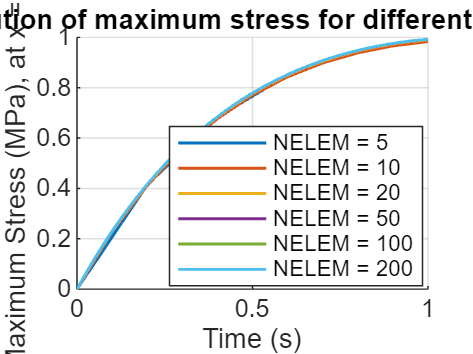



% Location of maximum stress for different NELEM values

figure;
hold on;
title('Evolution of maximum stress for different NELEM');
xlabel('Time (s)');
ylabel('Maximum Stress (MPa), at x = 0.5');
legendEntries = cell(length(NELEM_vec), 1);

% Loop through each NELEM value to plot the maximum stress at x = 0.5 over time
for e = 1:length(NELEM_vec)
    % Find the index of the Gauss coordinate closest to x = 0.5
    [~, indELEM] = min(abs(COOR_gauss{e} - 0.5));
    
    % Plot the maximum stress over time for this NELEM
    plot(TIMES{e}, STRESS_GLO{e}(indELEM, :), 'LineWidth', 1);
    legendEntries{e} = ['NELEM = ', num2str(NELEM_vec(e))];
end

grid on;
legend(legendEntries, 'Location', 'Best');